# Comparing Ice Thickness in the past decade

The [Climate Data Store](https://cds.climate.copernicus.eu/) is a wealth of information about the Earth's past, present and future climate.  It is freely available and functions as a one-stop shop to explore climate data. There are hundreds of data sets associated with climate change.

[The sea ice thickness dataset](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice-thickness) provides monthly gridded data of sea ice thickness for the Arctic region based on satellite radar altimetry observations. Sea ice is an important component of our climate system and a sensitive indicator of climate change. Its presence or its retreat has a strong impact on air-sea interactions, the Earth’s energy budget as well as marine ecosystems. It is recognized by the Global Climate Observing System as an Essential Climate Variable. Sea ice thickness is one of the parameters commonly used to characterize sea ice, alongside sea ice concentration, sea ice edge, and sea ice type, also available in the Climate Data Store.

## Download and Extract the ice thickness data from Climate Data Store

Select the sea ice thickness dataset

datasetName = "satellite-sea-ice-thickness";

Select the data to download from the dataset (see [this webpage](https://cds.climate.copernicus.eu/cdsapp#!/dataset/satellite-sea-ice-thickness?tab=form) for options).  This is a "MATLABized" version of the python structure that is generated in the API request.

datasetOptions.version = "3_0";
datasetOptions.variable = "all";
datasetOptions.satellite = ["envisat","cryosat_2"];
datasetOptions.cdr_type = ["cdr","icdr"];
datasetOptions.year = ["2004","2014","2024"];
datasetOptions.month = "03";

Download the data from Climate Data Store using `climateDataStoreDownload`.  It is put in a directory that starts with "satellite-sea-ice-thickness."

[downloadedFilePaths,citation] = climateDataStoreDownload(datasetName,datasetOptions);

2025-06-22 08:36:42,201 INFO [2025-06-16T00:00:00] CC-BY licence to replace Licence to use Copernicus Products on 02 July 2025. More information available [here](https://forum.ecmwf.int/t/cc-by-licence-to-replace-licence-to-use-copernicus-products-on-02-july-2025/13464)
2025-06-22 08:36:42,204 INFO [2025-06-10T00:00:00] To improve our C3S service, we need to hear from you! Please complete this very short [survey](https://confluence.ecmwf.int/x/E7uBEQ/). Thank you.
2025-06-22 08:36:42,204 INFO [2024-09-26T00:00:00] Watch our [Forum](https://forum.ecmwf.int/) for Announcements, news and other discussed topics.

ac3d822f5454958c7aaad92e6e3aea36.zip:   0%|          | 0.00/6.68M [00:00<?, ?B/s]
ac3d822f5454958c7aaad92e6e3aea36.zip:  15%|#4        | 1.00M/6.68M [00:01<00:06, 878kB/s]
ac3d822f5454958c7aaad92e6e3aea36.zip:  30%|##9       | 2.00M/6.68M [00:01<00:03, 1.48MB/s]
ac3d822f5454958c7aaad92e6e3aea36.zip:  45%|####4     | 3.00M/6.68M [00:02<00:03, 1.06MB/s]
ac3d822f5454958c7aaad92e6e3ae

downloadedFilePaths

downloadedFilePaths = 3×1 string array
    "satellite-sea-ice-thickness-20250622083656\ice_thickness_nh_ease2-250_cdr-v3p0_200403.nc"
    "satellite-sea-ice-thickness-20250622083656\ice_thickness_nh_ease2-250_cdr-v3p0_201403.nc"
    "satellite-sea-ice-thickness-20250622083656\ice_thickness_nh_ease2-250_icdr-v3p0_202403.nc"


The function also returns the appropriate citation for the data

disp(citation)

Generated using Copernicus Climate Change Service information 2025


## Explore the ice thickness data

Look at the third file (March 2024) to get variable information

info = ncinfo(downloadedFilePaths(3));
info.Variables

ans = 1×11 struct array with fields:
    Name
    Dimensions
    Size
    Datatype
    Attributes
    ChunkSize
    FillValue
    DeflateLevel
    Shuffle


## Read and format ice thickness data from 2004, 2014 and 2024

Transform and load the latitude, longitude, and ice thickness.  

ice2004 = readSatelliteSeaIceThickness(downloadedFilePaths(1));
ice2014 = readSatelliteSeaIceThickness(downloadedFilePaths(2));
ice2024 = readSatelliteSeaIceThickness(downloadedFilePaths(3));
head(ice2024)

       time         lat       lon      thickness
    ___________    ______    ______    _________

    01-Mar-2024    45.095     144.8      0.27285
    01-Mar-2024    44.954    144.56      0.63064
    01-Mar-2024    45.294    144.63     -0.15743
    01-Mar-2024    45.152    144.39     0.078858
    01-Mar-2024    45.632     144.7       0.0514
    01-Mar-2024    45.492    144.46     -0.07877
    01-Mar-2024    45.064    143.75    0.0017366
    01-Mar-2024    45.971    144.78      0.86787



## Visually compare March ice thickness in 2004, 2014 and 2024

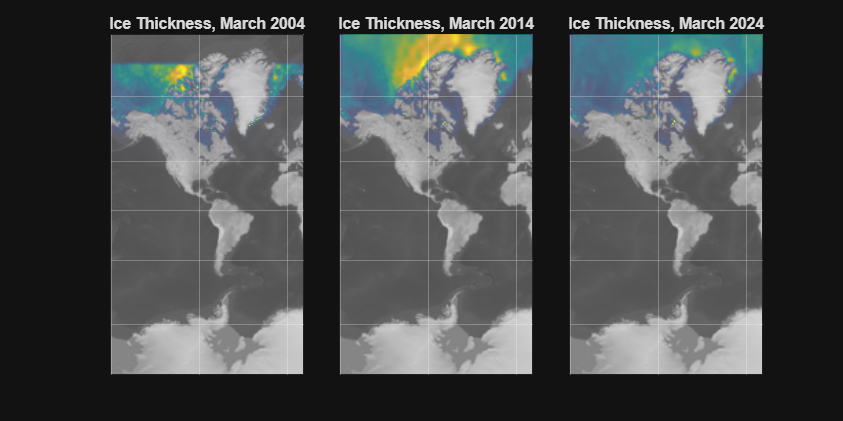

tiledlayout("horizontal","TileSpacing","tight")

nexttile
p = geodensityplot(ice2004.lat,ice2004.lon,ice2004.thickness,"FaceColor","interp");
p.Parent.LatitudeAxis.Visible = "off";
p.Parent.LongitudeAxis.Visible = "off";
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2004")


nexttile
p = geodensityplot(ice2014.lat,ice2014.lon,ice2014.thickness,"FaceColor","interp");
p.Parent.LatitudeAxis.Visible = "off";
p.Parent.LongitudeAxis.Visible = "off";
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2014")

nexttile
p = geodensityplot(ice2024.lat,ice2024.lon,ice2024.thickness,"FaceColor","interp");
p.Parent.LatitudeAxis.Visible = "off";
p.Parent.LongitudeAxis.Visible = "off";
geolimits([23 85],[-181.4 16.4])
geobasemap("grayterrain")
title("Ice Thickness, March 2024")
f = gcf;
f.Position(3) = f.Position(4)*2;

disp(citation)

Generated using Copernicus Climate Change Service information 2025


Clean up the downloaded files

[downloadDirectory,~,~] = fileparts(downloadedFilePaths(1));
rmdir(downloadDirectory,'s')

Copyright 2021-2025 The MathWorks, Inc.